# Errores en estado estacionario

Sirve para completar el analisis de estabilidad.

3 entradas:

- Entrada de posicion

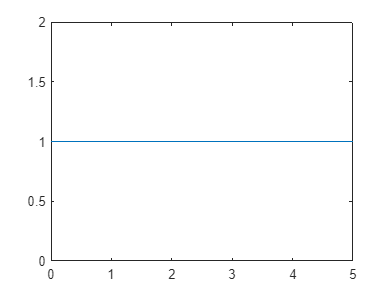

fplot(@(x) 1, [0 5])

- Entrada de velocidad

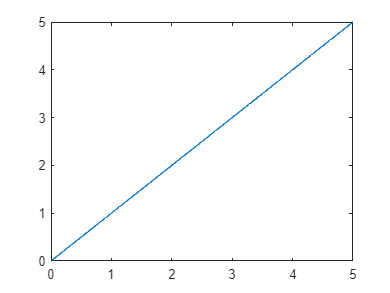

fplot(@(x) x, [0 5])

- Entrada de aceleracion

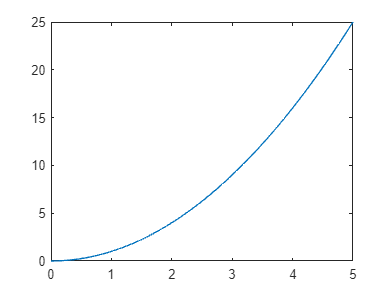

fplot(@(x) x*x, [0 5])

## Formula:

Del diagrama de flujo en lazo cerrado optenemos las siguiente ecuaciones:


$$E\left(s\right)=R\left(s\right)-Y\left(s\right)*H\left(s\right)$$



$$Y\left(s\right)=E\left(s\right)*G\left(s\right)$$



$$E\left(s\right)=R\left(s\right)-E\left(s\right)*G\left(s\right)*H\left(s\right)$$



$$E\left(s\right)\left\lbrack 1+G\left(s\right)*H\left(s\right)\right\rbrack =R\left(s\right)$$


Obtenemos:


$$E\left(s\right)=\frac{R\left(s\right)}{1+G\left(s\right)*H\left(s\right)}$$


## Ruido:

Siempre necesitaremos un filtro por el ruido.

Oamps recomendados

- **LF353**

- INA128

- AD620

## Teorema del valor final


$$e_{\infty } =\lim_{s\to 0} \frac{R\left(s\right)}{1+G\left(s\right)*H\left(s\right)}$$


Con el teorema de valor final obtendremos cada una de las formulas para cada tipo de entrada:

### Error de posicion(Entrada Escalar)


$$ep_{\infty } =\frac{1}{1+\lim_{s\to 0} G\left(s\right)*H\left(s\right)}=\frac{1}{{1+k}_p }$$


donde:


$$k_p =\lim_{s\to 0} G\left(s\right)*H\left(s\right)$$


A kp se le conoce como ***constante de posicòn.***

### Error de velocidad(Entrada rampa)


$$ev_{\infty } =\frac{1}{\lim_{s\to 0} \;s*G\left(s\right)*H\left(s\right)}=\frac{1}{k_v }$$


donde:


$$k_v =\lim_{s\to 0} \;s*G\left(s\right)*H\left(s\right)$$


A kv se le conoce como ***constante de velocidad.***

### Error de aceleracion(entrada parabolica)


$$ea_{\infty } =\frac{1}{\lim_{s\to 0} \;s^2 *G\left(s\right)*H\left(s\right)}=\frac{1}{k_a }$$


donde:


$$k_a =\lim_{s\to 0} \;s^2 *G\left(s\right)*H\left(s\right)$$


A ka se le conoce como ***constante de aceleracion.***

## Tipo de un sistema

Se define ***tipo de un sitema ***como el orden del polo en el origen de la funcion de transferencia en cadena abierta del sistema


$$G\left(s\right)=\frac{\left(s-a_1 \right)\left(s-a_2 \right)\ldotp \ldotp \ldotp \left(s-a_n \right)}{s^N \left(s-b_1 \right)\left(s-b_2 \right)\ldotp \ldotp \ldotp \left(s-b_p \right)}$$


Segun aumenta el tipo del sistema, aumenta tambien su precision. En la siguiente tabla puede verse como varia el error ante diferentes entradas en funcion del sisteman.